# ME 140 HW 6 - Open Roots 10.2

## Problem 1 - Fixed-point iteration

Consider the function

f(x)=sin(√x)−x

Employ fixed-point iteration with an initial guess of *x*0 = 0.5 to locate the root of the given function and iterate until |εa|≤0.01% . (Round the final answer to four decimal places.)

% help fixpt
% gotta solve for x. I'd rather have matlab do for me
x0 = 0.5; es = 0.01; 
f = @(x) sin(sqrt(x))-x;

% solve for g
% set = 0, get x on one side
g = @(x) sin(sqrt(x));
[x1,ea,iter] = fixpt(g,x0,es)

x1 = 0.7686

ea = 0.0097

iter = 9

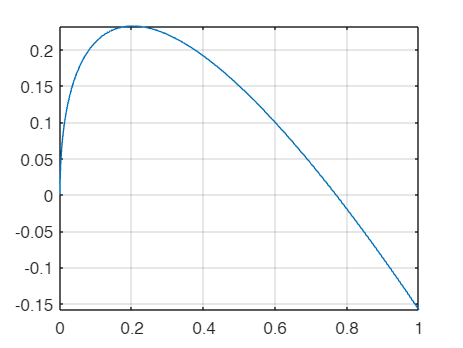


fplot(f, [0 1]); hold off; grid;

%{ 
% Not currently working
% Automatic f -> g(x)
syms x
fSym = f(x);              % Convert numeric function handle f into a symbolic expression
eqn = fSym == 0;          % Create the symbolic equation f(x) = 0

gSym = rhs(isolate(eqn, x)) % Rearrange equation to izolate x, then take the right-hand side (g(x))

g = matlabFunction(gSym); % convert back to ftn handle

% use fixpt
[x1,ea,iter] = fixpt(g,x0,es)

% or, use my automatic g calculator version
[x1,ea,iter] = fixpt_autog(f,x0,es)
%}

## Problem 2 - Finding roots by using MATLAB

Consider the function 

*f*(*x*) = *x*3 − 6*x*2 + 11*x* − 6.1

Determine the roots of the given function using MATLAB. (Round the final answers to four decimal places and write them in descending order.)

r_f = roots([1 -6 11 -6.1])

r_f =     3.0467
    1.8990
    1.0544



% or if given f
syms x;
f = @(x) x^3 - 6*x^2 + 11*x - 6.1;
coeff = sym2poly(f(x)); % Gets in vector form
r_coeff = roots(coeff)

r_coeff =     3.0467
    1.8990
    1.0544


## Problem 3 - Finding root by Newton Raphson method

Consider the function

*f*(*x*) = *x*5 − 16.05*x*4 + 88.75*x*3 − 192.0375*x*2 + 116.35*x* + 31.6875

Determine the root of the given function using the Newton-Raphson method with an initial guess *x*0 = 0.5825 and *ε**s* = 0.01%. (Round the final answer to two decimal places.)

syms x;
f = @(x) x^5 - 16.05*x^4 + 88.75*x^3 - 192.0375*x^2 + 116.35*x + 31.6875;
df_sym = diff(f,x);
df = matlabFunction(df_sym);
domain = [-0.5 7];
fplot(f, domain); 

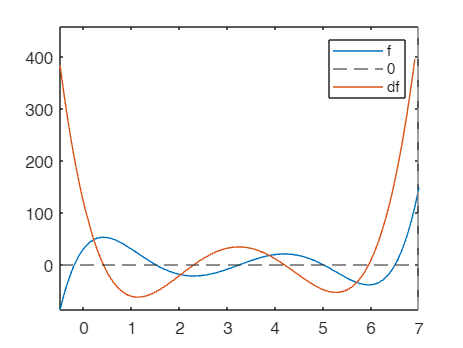

hold on;
yline(0,'--'), fplot(df, domain);
legend('f', '0','df');
hold off;


% help newtraph
func = f; dfunc = df; xr = 0.5825; es = 0.01;
[root,ea,iter]=newtraph(func,dfunc,xr,es)

root = 6.5000

ea = 2.6849e-04

iter = 22

% goes to 6.5 bc shoots it all the way over to right (bunch of roots and
% rapid slope changes make this bad for the Newton's method)

## Problem 4 - modified secant method

Consider the function

*f*(*x*) = *x*5 − 16.05*x*4 + 88.75*x*3 − 192.0375*x*2 + 116.35*x* + 31.6875

Determine the root of the given function using the modified secant method with *δ* = 0.05. Use an initial guess of *x*0 = 0.5825 and *ε**s* = 0.01%. (Round the final answer to two decimal places. Include a minus sign if necessary.)

% help modSecant
f = @(x) x^5 - 16.05*x^4 + 88.75*x^3 - 192.0375*x^2 + 116.35*x + 31.6875;
delta = 0.05; x0 = 0.5825; tol = 0.01;
xr=modSecant(f,x0,delta,tol)

xr = -0.2000

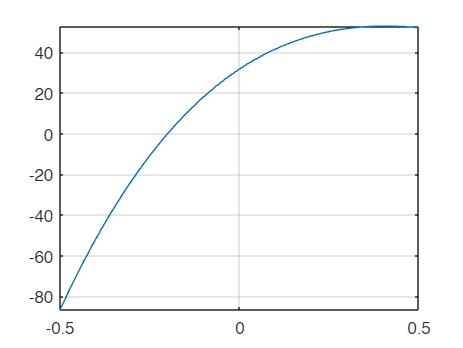

fplot(f, [-0.5 0.5]); grid;

% Gets the left root instead of 6.5 bc left is closer

## Problem 5 - Compression of a nonlinear spring

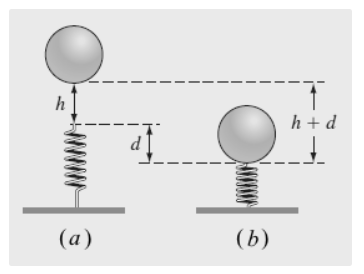

Real mechanical systems may involve the deflection of nonlinear springs. In the given figure, a block of mass *m* is released a distance *h* above a nonlinear spring. The resistance force F of the spring is given by

F=−(k1d+k2d3/2)

Conservation of energy can be used to show that

0=2k2d5/25+12k1d2−mgd−mgh

Solve for *d*, given the following parameter values: *k*1 = 40,000 g/s2, *k*2 = 40 g/(s2 m0.5), *m* = 95 g, *g* = 9.81 m/s2, and *h* = 0.52 m. (Round the final answer to four decimal places.)

#### Matlab Equation Solver

syms d k1 k2 m g h

eqn = (2*k2*d^(5/2))/5 + (1/2)*k1*d^2 - m*g*d - m*g*h == 0; % == 0 necessary for eq

sol_d = solve(eqn, d);

pretty(sol_d) % didn't work bc can't solve for d. Why doing numerical method breh

()



#### Calc Results

k1 = 40000;    % g/s2, 
k2 = 40;        % g/(s2 m0.5)
m = 95;         % g
g = 9.81;       % m/s2
h = 0.52;       % m

eqn_ftn = @(d) (2*k2*d^(5/2))/5 + (1/2)*k1*d^2 - m*g*d - m*g*h;
fplot(eqn_ftn, [0 0.4])

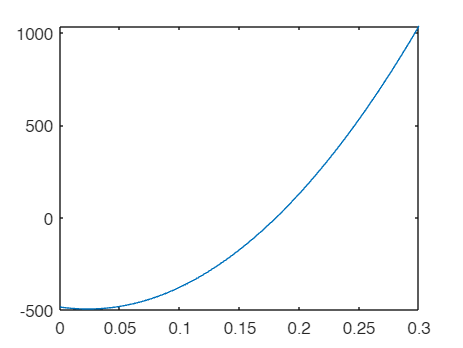

hold off;


x0 = 0.2; % based on the graph
x1 = 0.1; x2 = 0.4; delta = 0.0001;

% Fixpt
g = @(d) ((2*k2*d^(5/2))/5 + (1/2)*k1*d^2 - m*g*h)/(m*g);
[x1,ea,iter] = fixpt(g,x0)

x1 = Inf

ea = NaN

iter = 50

% THIS WON'T WORK. Remember Math 121 and the constraints
%        If all of g(x) on [a,b] has a range within [a,b], there's at least one fixed point on the interval.
%        If (1) and g'(x) (the slope) is always within [-1,1], then the fixed point is unique.
%        We want to find situations where both 1 and 2 apply before we use g(x)
% In this case, neither 1 nor 2 are satisfied. Not good for fixpt

% Newtraph
%   Hecka hard to find deriv, I don't want to.

% Secant
%   help secant
% xr_sec=secant(eqn,x1,x2)
% Failed bc slope so steep. Picking two far away points sent far.

% Mod secant
%   help modSecant
xr_mS=modSecant(eqn_ftn,x0,delta)

xr_mS = 0.1807

% Works bc small delta automatically fixes secant issue

% roots
%{
% Fails bc not polynomial w/ exponents 1 2 3...
syms d
coeff = sym2poly(eqn(d)); % Gets in vector form
r_coeff = roots(coeff)
%}

% fzero (safe bet)
root_fz = fzero(eqn_ftn, x0) % what the book uses. Your best bet.

root_fz = 0.1807

% root_fz_2 = fzero(eqn_ftn, [x1 x2]) % didn't work bc x2 too large?

Error using fzero (line 214)
Second argument must be finite.

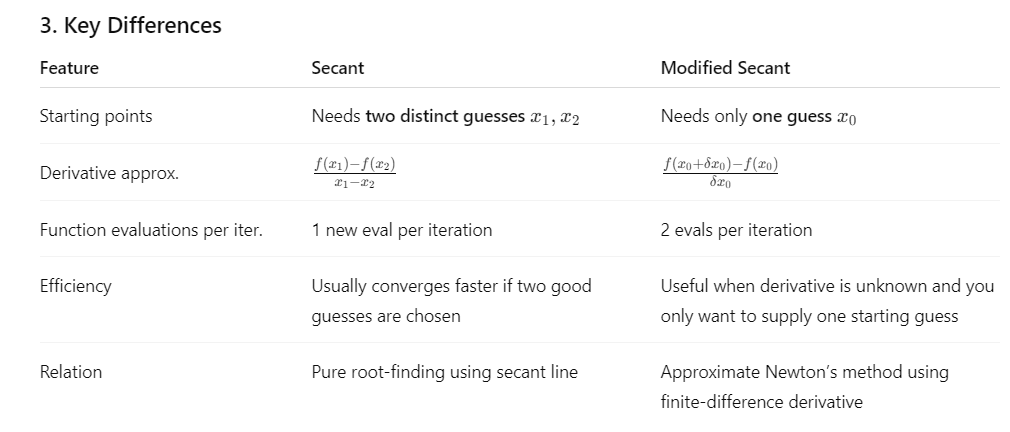

- Secant ≈ Newton-Raphson without derivatives, but with two guesses.

- Modified Secant ≈ Newton-Raphson without derivatives, but using one guess and a small perturbation δ.